clc;clear;
nrow=200;
load posterior_SP_bs_ENV.mat
post_dist=zeros(nrow,10000);
for i=1:nrow
    post_dist(i,:) = randi([1 12000],1,10000) ;
end
cov = linspace(-2.8,2.8,nrow)';


mean_slope=mean(slope1_bs_M,"all");
mu=mean(M_bs);
points = invlogit(logit(M_bs(post_dist))+slope1_bs_M(post_dist).*cov);
mean_line = invlogit(logit(mean(mu))+mean_slope*cov);
SEM = std(points,0,2);               % Standard Error
ts = tinv([0.025  0.975],nrow-1);      % T-Score
CI = mean_line + ts.*SEM;                      % Confidence Intervals
fig=figure;
fig.Position=[560,240,350,400]

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 240 350 400]
       Units: 'pixels'

  Show all properties


hold on
%scatter(cov,points(:,6),25,[153, 204, 255]/256)
h1=plot (cov, mean_line,"LineWidth",2,"Color",[0 102 204]/256);
plot(cov(1:3:end),CI((1:3:end),1),"--","Color",[0 102 204]/256,"LineWidth",0.3)
plot(cov(1:3:end),CI((1:3:end),2),"--","Color",[0 102 204]/256,"LineWidth",0.3)
ciplot( CI(:,1), CI(:,2), cov ,[153, 204, 255]/256);

plot_handle =   Patch with properties:

    FaceColor: [0.5977 0.7969 0.9961]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×400 double)
     Vertices: [400×2 double]

  Show all properties


ylabel('Breeding success');xlabel('Number of snow days');
pbaspect([1 1 1]);box off;
ylim([0 1]);xlim([-3 3]);xticks([-3 0 3])
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
set(gca,'TickDir','out'); 
%%%
mean_slope=mean(slope1_bs_F,"all");
mu=mean(F_bs);
points = invlogit(logit(F_bs(post_dist))+slope1_bs_F(post_dist).*cov);
mean_line = invlogit(logit(mean(mu))+mean_slope*cov);
SEM = std(points,0,2);               % Standard Error
ts = tinv([0.025  0.975],nrow-1);      % T-Score
CI = mean_line + ts.*SEM;                      % Confidence Intervals
%scatter(cov,points(:,6),25,[153, 204, 255]/256)
h2=plot (cov, mean_line,"LineWidth",2,"Color",[153 51 51]/256);
plot(cov(1:3:end),CI((1:3:end),1),"--","Color",[153 51 51]/256,"LineWidth",0.3)
plot(cov(1:3:end),CI((1:3:end),2),"--","Color",[153 51 51]/256,"LineWidth",0.3)
ciplot( CI(:,1), CI(:,2), cov ,[225 175 175]/256);

plot_handle =   Patch with properties:

    FaceColor: [0.8789 0.6836 0.6836]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×400 double)
     Vertices: [400×2 double]

  Show all properties


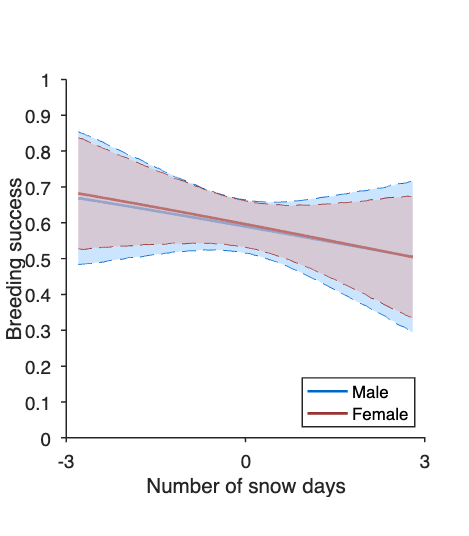

ylabel('Breeding success');xlabel('Number of snow days');
pbaspect([1 1 1]);box off;
ylim([0 1]);xlim([-3 3]);xticks([-3 0 3])
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
set(gca,'TickDir','out'); 
legend([h1(1),h2(1)],'Male','Female',Location='southeast')
exportgraphics(fig,'bs_full/bs_nsnow.pdf','BackgroundColor','none')
exportgraphics(fig,'bs_full/bs_nsnow.png','BackgroundColor','none')

mean_slope=mean(slope2_bs_M,"all");
mu=mean(M_bs);
points = invlogit(logit(M_bs(post_dist))+slope2_bs_M(post_dist).*cov);
mean_line = invlogit(logit(mean(mu))+mean_slope*cov);
SEM = std(points,0,2);               % Standard Error
ts = tinv([0.025  0.975],nrow-1);      % T-Score
CI = mean_line + ts.*SEM;                      % Confidence Intervals
fig=figure;
fig.Position=[560,240,350,400]

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 240 350 400]
       Units: 'pixels'

  Show all properties


hold on
%scatter(cov,points(:,6),25,[153, 204, 255]/256)
h1=plot (cov, mean_line,"LineWidth",2,"Color",[0 102 204]/256);
plot(cov(1:3:end),CI((1:3:end),1),"--","Color",[0 102 204]/256,"LineWidth",0.3)
plot(cov(1:3:end),CI((1:3:end),2),"--","Color",[0 102 204]/256,"LineWidth",0.3)
ciplot( CI(:,1), CI(:,2), cov ,[153, 204, 255]/256);

plot_handle =   Patch with properties:

    FaceColor: [0.5977 0.7969 0.9961]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×400 double)
     Vertices: [400×2 double]

  Show all properties


ylabel('Breeding success');xlabel('Number of snow days');
pbaspect([1 1 1]);box off;
ylim([0 1]);xlim([-3 3]);xticks([-3 0 3])
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
set(gca,'TickDir','out'); 
%%%
mean_slope=mean(slope2_bs_F,"all");
mu=mean(F_bs);
points = invlogit(logit(F_bs(post_dist))+slope2_bs_F(post_dist).*cov);
mean_line = invlogit(logit(mean(mu))+mean_slope*cov);
SEM = std(points,0,2);               % Standard Error
ts = tinv([0.025  0.975],nrow-1);      % T-Score
CI = mean_line + ts.*SEM;                      % Confidence Intervals
%scatter(cov,points(:,6),25,[153, 204, 255]/256)
h2=plot (cov, mean_line,"LineWidth",2,"Color",[153 51 51]/256);
plot(cov(1:3:end),CI((1:3:end),1),"--","Color",[153 51 51]/256,"LineWidth",0.3)
plot(cov(1:3:end),CI((1:3:end),2),"--","Color",[153 51 51]/256,"LineWidth",0.3)
ciplot( CI(:,1), CI(:,2), cov ,[225 175 175]/256);

plot_handle =   Patch with properties:

    FaceColor: [0.8789 0.6836 0.6836]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×400 double)
     Vertices: [400×2 double]

  Show all properties


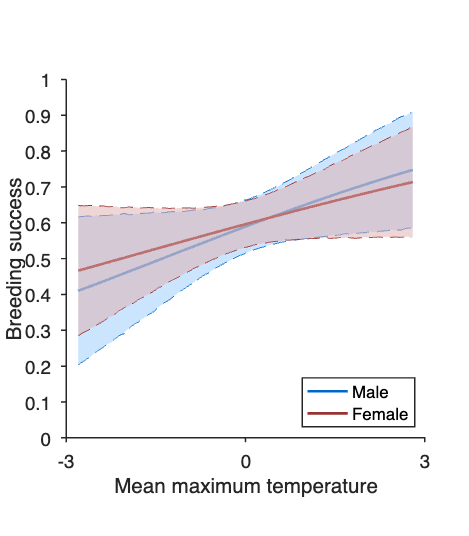

ylabel('Breeding success');xlabel('Mean maximum temperature');
pbaspect([1 1 1]);box off;
ylim([0 1]);xlim([-3 3]);xticks([-3 0 3])
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
set(gca,'TickDir','out'); 
legend([h1(1),h2(1)],'Male','Female',Location='southeast')
exportgraphics(fig,'bs_full/bs_maxT.pdf','BackgroundColor','none')
exportgraphics(fig,'bs_full/bs_maxT.png','BackgroundColor','none')

mean_slope=mean(slope3_bs_M,"all");
mu=mean(M_bs);
points = invlogit(logit(M_bs(post_dist))+slope3_bs_M(post_dist).*cov);
mean_line = invlogit(logit(mean(mu))+mean_slope*cov);
SEM = std(points,0,2);               % Standard Error
ts = tinv([0.025  0.975],nrow-1);      % T-Score
CI = mean_line + ts.*SEM;                      % Confidence Intervals
fig=figure;
fig.Position=[560,240,350,400]

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 240 350 400]
       Units: 'pixels'

  Show all properties


hold on
%scatter(cov,points(:,6),25,[153, 204, 255]/256)
h1=plot (cov, mean_line,"LineWidth",2,"Color",[0 102 204]/256);
plot(cov(1:3:end),CI((1:3:end),1),"--","Color",[0 102 204]/256,"LineWidth",0.3)
plot(cov(1:3:end),CI((1:3:end),2),"--","Color",[0 102 204]/256,"LineWidth",0.3)
ciplot( CI(:,1), CI(:,2), cov ,[153, 204, 255]/256);

plot_handle =   Patch with properties:

    FaceColor: [0.5977 0.7969 0.9961]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×400 double)
     Vertices: [400×2 double]

  Show all properties


ylabel('Breeding success');xlabel('Number of snow days');
pbaspect([1 1 1]);box off;
ylim([0 1]);xlim([-3 3]);xticks([-3 0 3])
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
set(gca,'TickDir','out'); 
%%%
mean_slope=mean(slope3_bs_F,"all");
mu=mean(F_bs);
points = invlogit(logit(F_bs(post_dist))+slope3_bs_F(post_dist).*cov);
mean_line = invlogit(logit(mean(mu))+mean_slope*cov);
SEM = std(points,0,2);               % Standard Error
ts = tinv([0.025  0.975],nrow-1);      % T-Score
CI = mean_line + ts.*SEM;                      % Confidence Intervals
%scatter(cov,points(:,6),25,[153, 204, 255]/256)
h2=plot (cov, mean_line,"LineWidth",2,"Color",[153 51 51]/256);
plot(cov(1:3:end),CI((1:3:end),1),"--","Color",[153 51 51]/256,"LineWidth",0.3)
plot(cov(1:3:end),CI((1:3:end),2),"--","Color",[153 51 51]/256,"LineWidth",0.3)
ciplot( CI(:,1), CI(:,2), cov ,[225 175 175]/256);

plot_handle =   Patch with properties:

    FaceColor: [0.8789 0.6836 0.6836]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×400 double)
     Vertices: [400×2 double]

  Show all properties


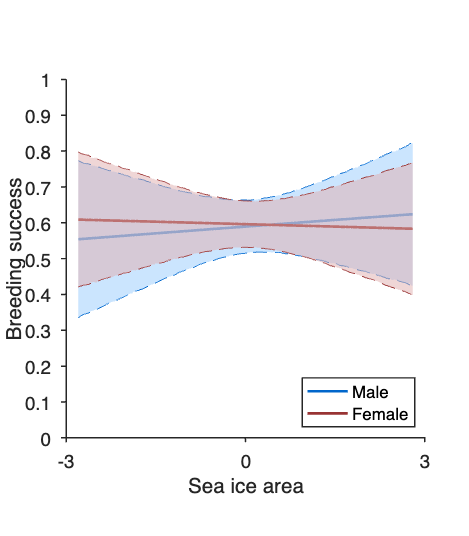

ylabel('Breeding success');xlabel('Sea ice area');
pbaspect([1 1 1]);box off;
ylim([0 1]);xlim([-3 3]);xticks([-3 0 3])
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
set(gca,'TickDir','out'); 
legend([h1(1),h2(1)],'Male','Female',Location='southeast')
exportgraphics(fig,'bs_full/bs_aice.pdf','BackgroundColor','none')
exportgraphics(fig,'bs_full/bs_aice.png','BackgroundColor','none')